# Lab 4

This lab focuses on morphological operators. This is the full list of morphological operations:

- `imerode`

- `imdilate`

- `imopen`

- `imclose`

- `imtophat`

- `imbothat`

- `imclearborder`

- `imkeepborder`

- `imfill`

- `bwhitmiss`

- `bwmorph`

- `bwmorph3`

- `bwperim`

- `bwskel`

- `bwulterode`

`> `Review these functions and identify their roles and why they might be useful

## Task 1: Dilation and Erosion

### Dilation

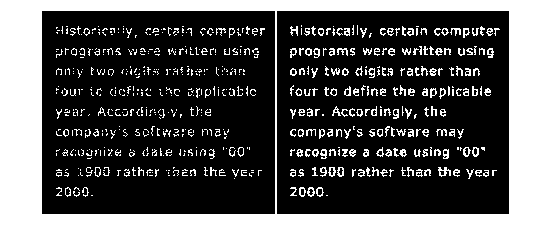

A = imread('assets/text-broken.tif');
B1 = [0 1 0;
     1 1 1;
     0 1 0];    % create structuring element
A1 = imdilate(A, B1);
montage({A,A1})

> Explain how dilation theoretically works

Using a structuring element of all ones:

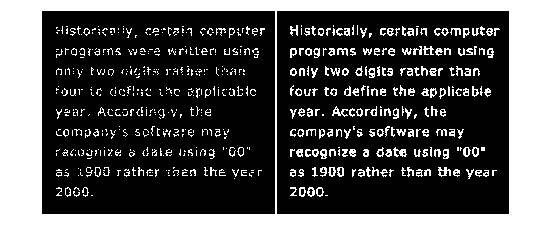

B2 = ones(3,3);     % generate a 3x3 matrix of 1's

A2 = imdilate(A, B2);
montage({A,A2})

This increases the dilation effect.

> Explain why the output changes in this way

Increasing the size of the structuring element:

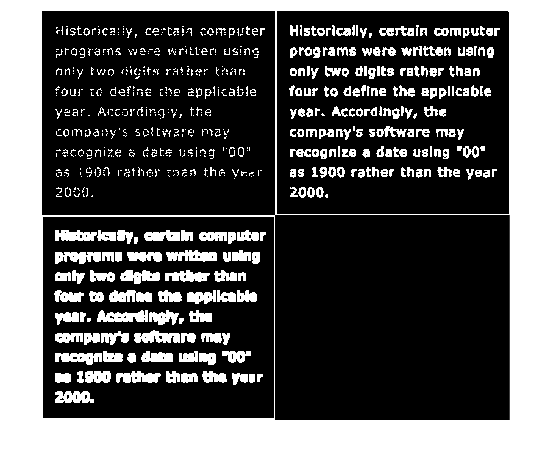

B3 = ones(5,5);    
B4 = ones(10,10);

A3 = imdilate(A, B3);
A4 = imdilate(A, B4);
montage({A,A3, A4})

It can be seen increasing the size of the structuring element increases the dilation effect, making the text appear thicker and eventually illegible - this suggests finding the correct SE size is quite important e.g. if the task was to improve text legibility.

Using a SE diagonal cross:

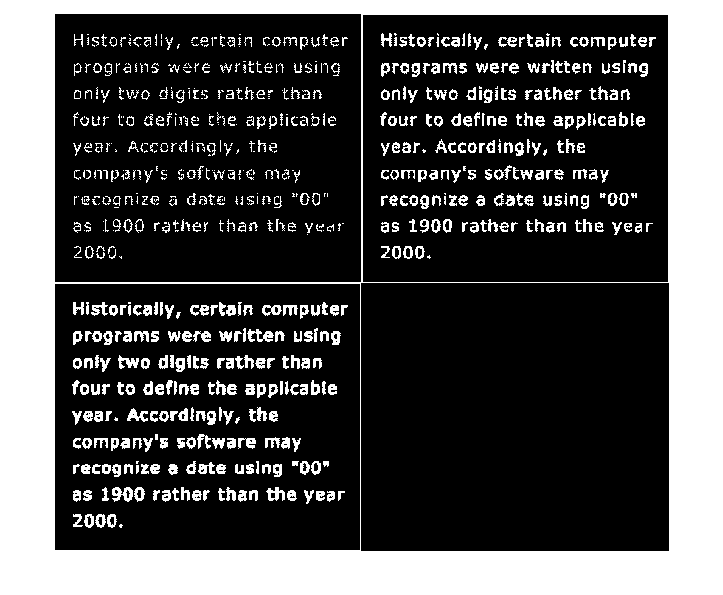

Bx = [1 0 1;
      0 1 0;
      1 0 1];

Bxx = [1 0 0 0 1;
       0 1 0 1 0;
       0 0 1 0 0;
       0 1 0 1 0;
       1 0 0 0 0];
% by increasing the size of the structuring element we can better observe
% the effect of the cross element 

Ax = imdilate(A, Bx);
Axx = imdilate(A, Bxx);
montage({A, Ax, Axx});

### Generation of Structuring Element

For spatial filtering, we used function `fspecial` to generate our filter kernel. For morphological operations, we use function *strel* to generate different kinds of structuring elements.

List of SE that `strel` can generate:

- `SE = strel ("diamond", r)`

- `SE = strel("disk", r)`

- `SE = strel("disk", r,n)`

- `SE = strel ("octagon", r)`

- `SE = strel("line", len, deg)`

- `SE = strel("rectangle", [m n] )`

- `SE = strel("square", w)`

> What is the difference between using `strel` and a user-defined SE matrix? 

> What might these different structuring elements be used for?

*strel* returns not a matrix, but an internal data structure called *strel*. This speeds up the execution of the morphological functions by Matlab.

> Are there any other reasons to use `strel` other than for execution speed? 

> What does the internal data structure look like?

SE = strel('disk',4);
SE.Neighborhood         % print the SE neighborhood contents

ans = 7×7 logical array
   0   0   1   1   1   0   0
   0   1   1   1   1   1   0
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   0   1   1   1   1   1   0
   0   0   1   1   1   0   0


> What is meant by Neighbourhood here? Will this be a smaller ratio if we use a larger SE?

- As the size increases the neighbour still seems to print the entire data structure:

SE = strel('disk',10);
SE.Neighborhood         % print the SE neighborhood contents

ans = 19×19 logical array
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1  

### Erosion Operation

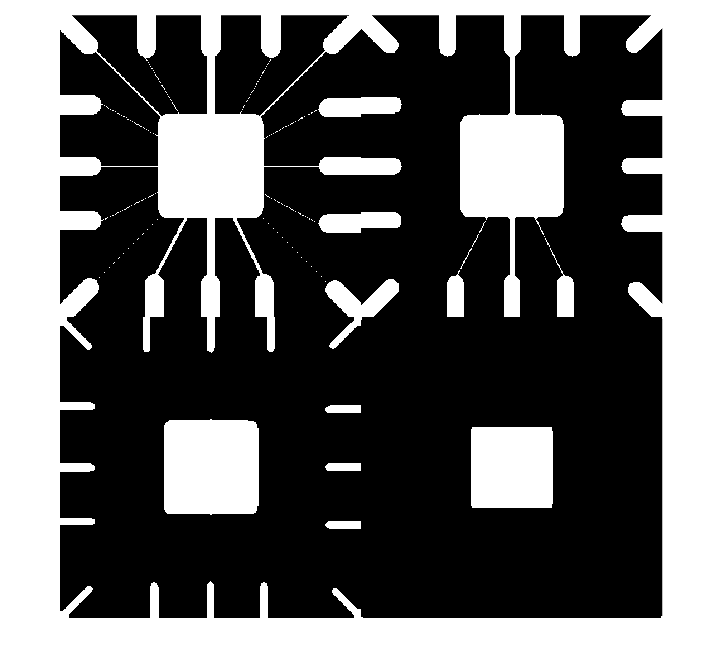

A = imread('assets/wirebond-mask.tif');
SE2 = strel('disk',2);
SE10 = strel('disk',10);
SE20 = strel('disk',20);
E2 = imerode(A,SE2);
E10 = imerode(A,SE10);
E20 = imerode(A,SE20);
montage({A, E2, E10, E20}, "size", [2 2])

As the disk size increases more erosion occurs meaning more positive parts of the image, represented by a binary value of 1 are removed, as a fewer proportion of sections (particularly thin, fine or very small sections) meet the criteria to pass the structuring element conditions (i.e. all pixels within the structuring element overlay being equal to 1]. This means increasing disk size removes more components in the image, starting with smaller components and removing larger components as disk size increases.

## Task 2 - Morphological Filtering with Open and Close

Opening = Erosion + Dilation

f = imread('assets/fingerprint-noisy.tif');

% the goal is to generate a 3x3 structuring element SE
% we cab define that with a basic ones matrix:
SE = ones(3,3);     % generate a 3x3 matrix of 1's

% but to improve processing speeds we may also want to use strel, for a 3x3
% strel we could use SE = strel("square", w); where w=3 and we can display
% the neighbourhood to confirm this is true

SE_strel = strel("square", 3);
disp(SE_strel.Neighborhood);

   1   1   1
   1   1   1
   1   1   1



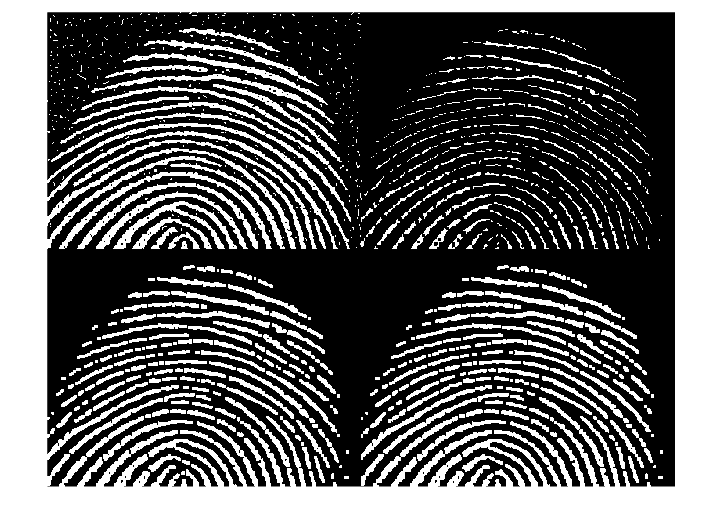


fe = imerode(f,SE);
fed = imdilate(fe,SE);
% this process in itself should be opebibf as it is erosion + dilation, but
% we can also use the built in function imopen and we can compare if there
% are any differences

fo = imopen(f,SE);
% we can see the effect looks nearly identical

montage({f, fe, fed, fo});

Eroding first removes some of the positive parts of the image - which can be helpful with removing noise. Dilating then enables us to bring back thickness to the original fingerprint lines without the original salt and pepper noise. Using the built in open function should have the identical effect. 

We can then improve `fo` using a close operation:

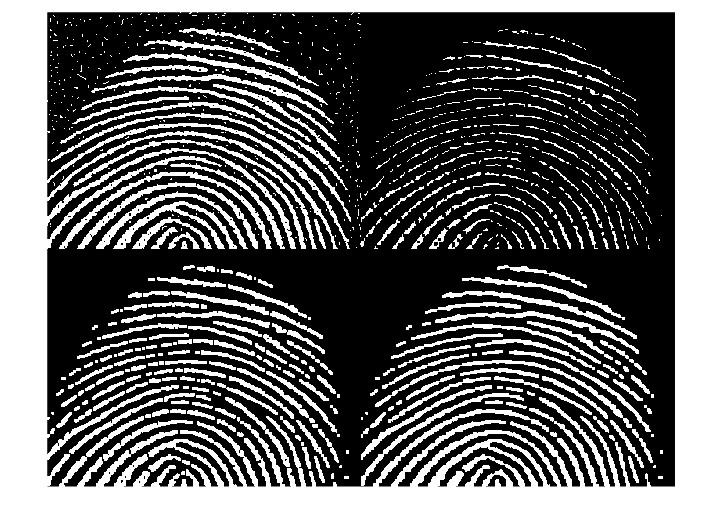

fc = imclose(fo,SE);
montage({f, fe, fo, fc});

> What does this achieve?

Comparing morphological filtering with applying a Gaussian filter:

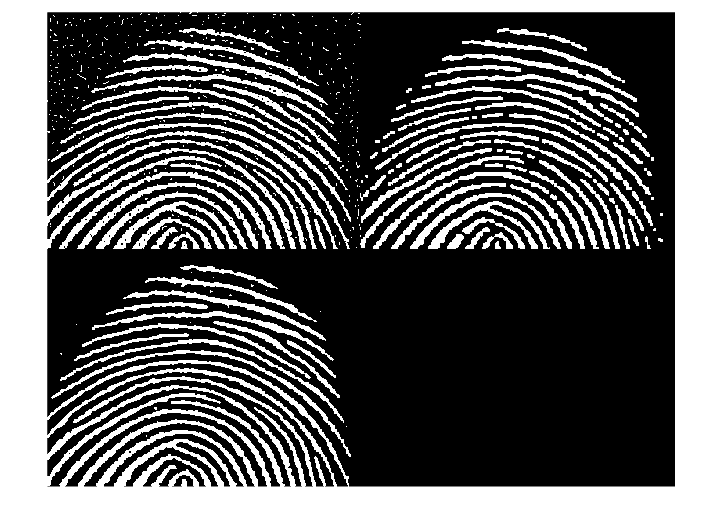

w_gauss = fspecial('Gaussian', [7 7], 1.0);
g_gauss = imfilter(f, w_gauss, 0);
montage({f, fc, g_gauss});

A guassian filter is a linear operation - which uses filter kernels. It can be considered a lowpass filter. 

We can see here that the opening, followed by closing morphological operation is more successful at removing noise in this instance than the selected gaussian filter. We can compare to other gaussian kernels:

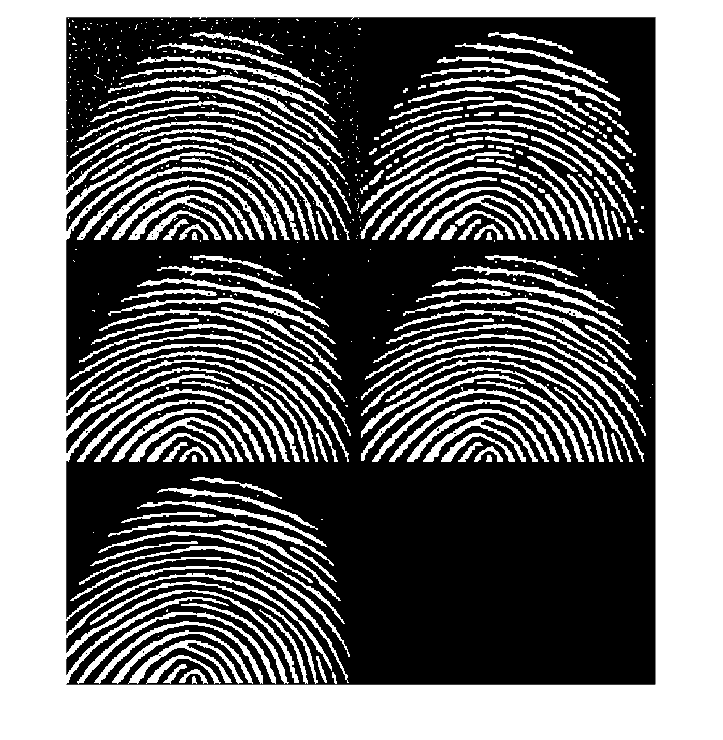

w1 = fspecial('Gaussian', [7 7], 0.8);
w2 = fspecial('Gaussian', [3 3], 1.0);
w3 = fspecial('Gaussian', [40 40], 1.0); 
% significantly increasing the size can remove more noise but there is still remaining noise 
% there might also be the potential of removing parts of the fingerprint we
% may want?

g1 = imfilter(f, w1, 0);
g2 = imfilter(f, w2, 0);
g3 = imfilter(f, w3, 0);

montage({f, fc, g1, g2, g3});

> Think more about the reasoning here - think more about the different trade-offs between the choice of these parameters and the effect on the image.

## Task 5 - Median Filtering

In both cases with Average and Gaussian filters, noise reduction is companied by reducing in the sharpness of the image. Median filter provides a better solution if sharpness is to be preserved.

> How does Median filtering work (e.g. from the mathematical perspective)?

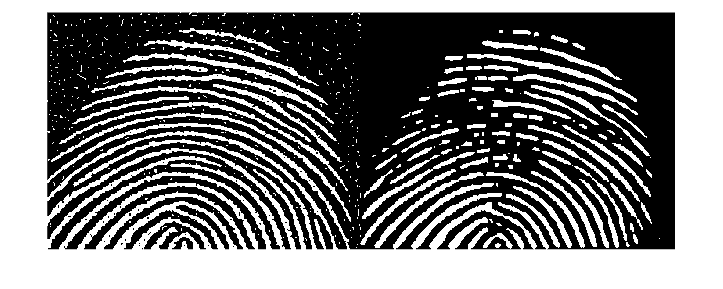

g_median = medfilt2(f, [7 7], 'zero');
montage({f, g_median});

In this case median filtering doesn't seem to be as good. It seems to remove parts of the image we want. So maybe adjusting some aspects can help. The sharpnes preservation isn't very clear either due to the low quality of the image.

> We can try using a higher quality image to observe the effects

> What happens if we use a non-zero padding - both in operation and theoretically?

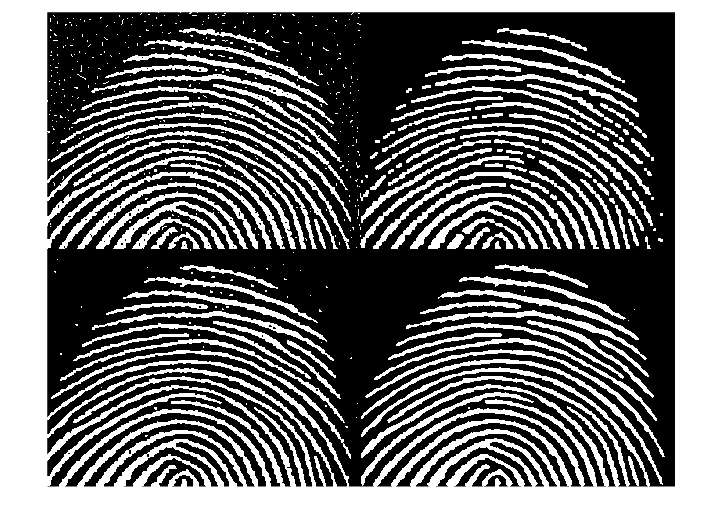

g_median = medfilt2(f, [4 4], 'zero');
montage({f, fc, g1, g_median});

% reducing the kernel size here helps to preserve more of the original
% image. I believe it may also be possible to see more of the sharpness
% preservation

More work could be done here

## Task 6 - Sharpening the image with Laplacian, Sobel and Unsharp filters

Now that you are familiar with the Matlab functions *fspecial* and *imfilter*, explore with various filter kernels to sharpen the moon image stored in the file *moon.tif*. The goal is to make the moon photo sharper so that the craters can be observed better.

Come back to this!